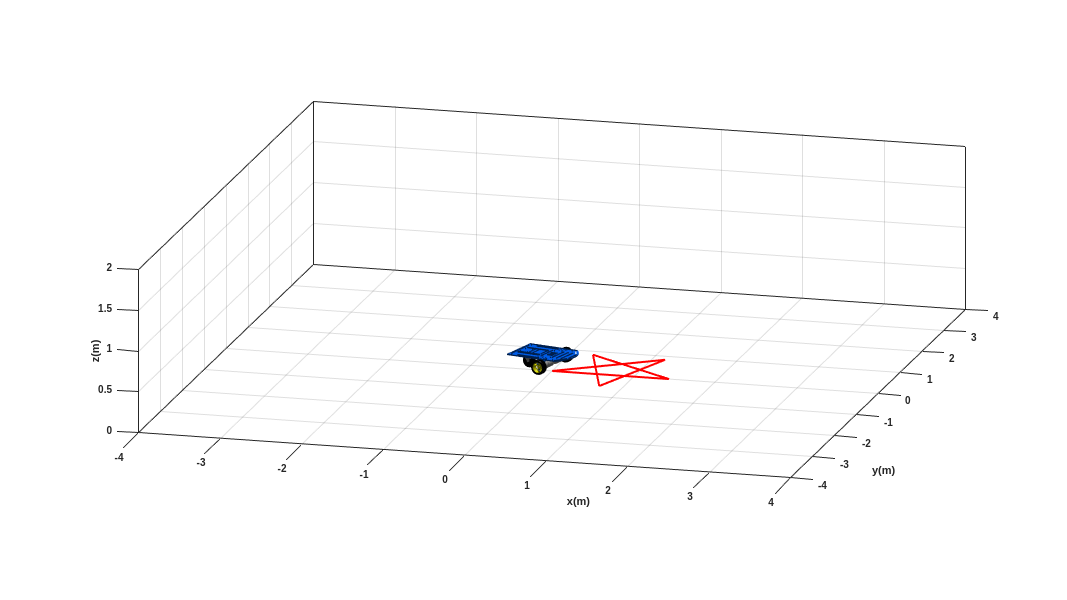

clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

ts = 0.1;             % Tiempo de muestreo
num_steps = 10;       % 12 pasos de la tabla
samples_per_step = 1 / ts; % 10 muestras por paso
N = num_steps * samples_per_step; % Total de muestras = 120
tf = N * ts;          % Tiempo total
t = 0:ts:tf;          % Vector de tiempo

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros(1, N+1);
y1 = zeros(1, N+1);
phi = zeros(1, N+1);

x1(1) = 0;
y1(1) = 0;
phi(1) = 0;

hx = zeros(1, N+1);
hy = zeros(1, N+1);
hx(1) = x1(1);
hy(1) = y1(1);

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES SEGÚN TABLA %%%%%%%%%%%%%%%%%%%%%%%%%%%%

v_table = [1.432 0 1.432 0 1.432 0 1.432 0 1.432 0];          % Velocidades lineales (v)
w_table = [0 2.513 0 2.513 0 2.513 0 2.513 0 2.513]; % Velocidades angulares (ω)

u = zeros(1, N);
w = zeros(1, N);

for i = 1:num_steps
    idx_start = (i-1)*samples_per_step + 1;
    idx_end = i*samples_per_step;
    u(idx_start:idx_end) = v_table(i);
    w(idx_start:idx_end) = w_table(i);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACIÓN %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k = 1:N
    phi(k+1) = phi(k) + w(k) * ts;
    xp1 = u(k) * cos(phi(k+1));
    yp1 = u(k) * sin(phi(k+1));
    x1(k+1) = x1(k) + xp1 * ts;
    y1(k+1) = y1(k) + yp1 * ts;
    hx(k+1) = x1(k+1);
    hy(k+1) = y1(k+1);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACIÓN 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

scene = figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen = get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([15 15]);
axis([-4 4 -4 4 0 2]);  % Ajusta según resultado

scale = 4;
MobileRobot_5;
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;
H2 = plot3(hx(1), hy(1), 0, 'r', 'lineWidth', 2);

step = 1;
for k = 1:step:N
    delete(H1);
    delete(H2);
    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'r', 'lineWidth', 2);
    pause(ts);
end

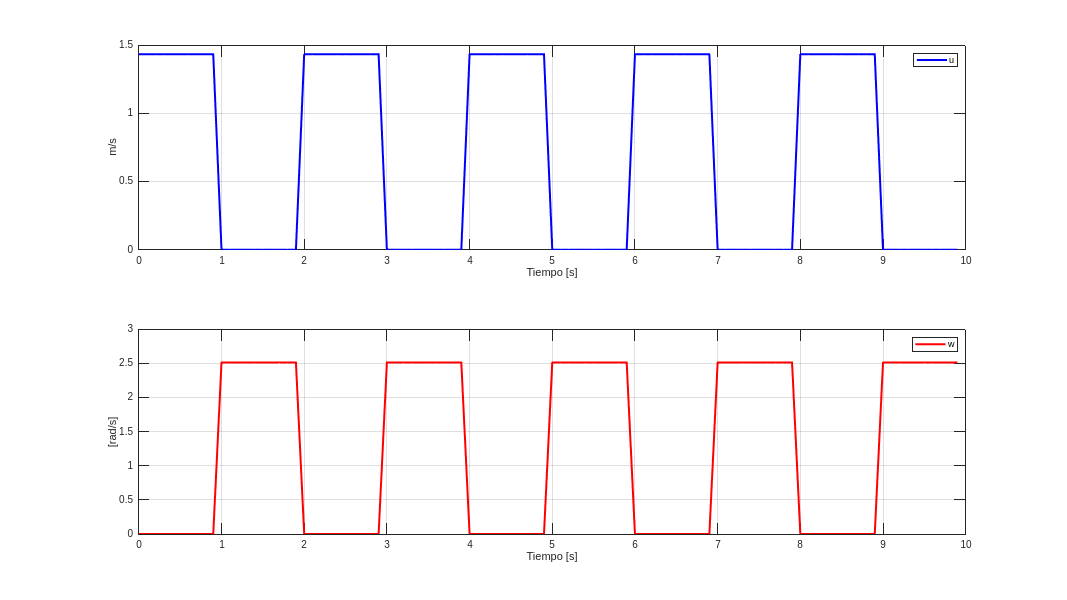


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

graph = figure;
set(graph, 'position', sizeScreen);

subplot(211)
plot(t(1:N), u, 'b', 'LineWidth', 2), grid on
xlabel('Tiempo [s]')
ylabel('m/s')
legend('u')

subplot(212)
plot(t(1:N), w, 'r', 'LineWidth', 2), grid on
xlabel('Tiempo [s]')
ylabel('[rad/s]')
legend('w')

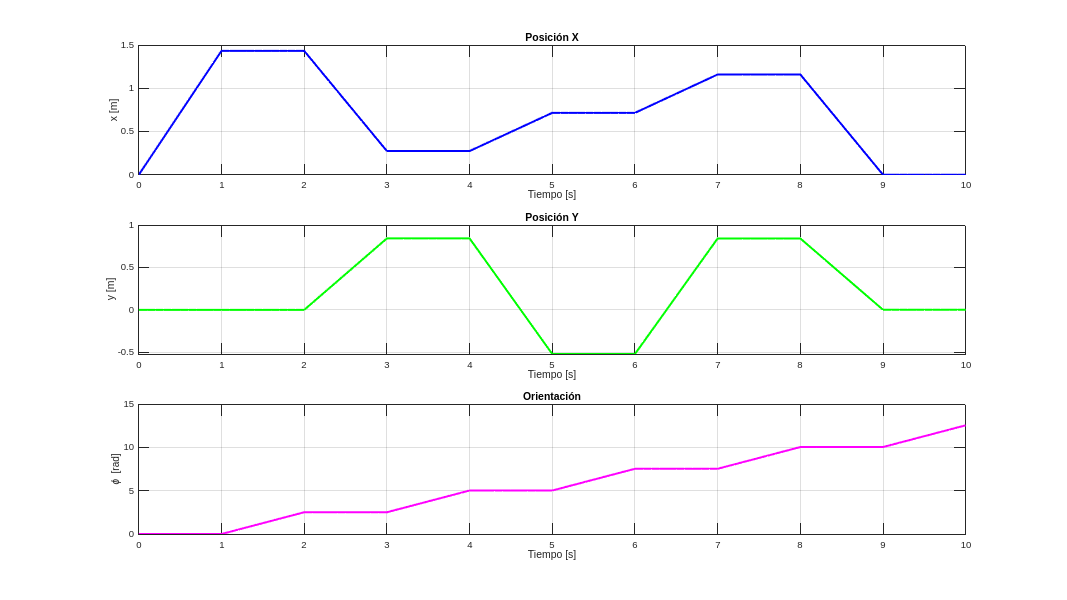


%%%%%%%%%%%%%%%%%%%%%%% GRAFICAR POSE %%%%%%%%%%%%%%%%%%%

pose_graph = figure;
set(pose_graph, 'position', sizeScreen);

subplot(311)
plot(t(1:N+1), x1, 'b', 'LineWidth', 2), grid on
xlabel('Tiempo [s]')
ylabel('x [m]')
title('Posición X');

subplot(312)
plot(t(1:N+1), y1, 'g', 'LineWidth', 2), grid on
xlabel('Tiempo [s]')
ylabel('y [m]')
title('Posición Y');

subplot(313)
plot(t(1:N+1), phi, 'm', 'LineWidth', 2), grid on
xlabel('Tiempo [s]')
ylabel('\phi [rad]')
title('Orientación');

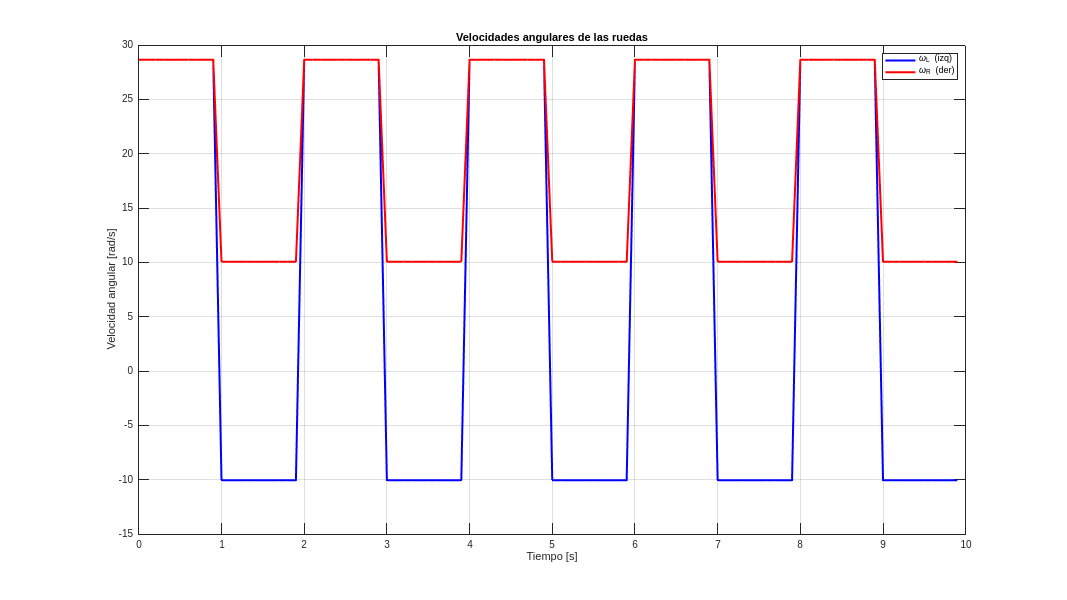


%%%%%%%%%%%%%%%%%%% CÁLCULO DE VELOCIDADES ANGULARES DE RUEDAS %%%%%%%%%%%%%%%%%%%

r = 0.05; % Radio de ruedas
L = 0.4;  % Distancia entre ruedas

wl = (2*u - w*L) / (2*r);
wr = (2*u + w*L) / (2*r);

wheel_graph = figure;
set(wheel_graph, 'position', sizeScreen);
plot(t(1:N), wl, 'b', 'LineWidth', 2), hold on
plot(t(1:N), wr, 'r', 'LineWidth', 2), grid on
xlabel('Tiempo [s]')
ylabel('Velocidad angular [rad/s]')
legend('\omega_L (izq)', '\omega_R (der)')
title('Velocidades angulares de las ruedas')


%%%%%%%%%%%%%%%%%%%%%%%%%% POSE CADA SEGUNDO (a) %%%%%%%%%%%%%%%%%%%%%%%%%%

indices_pasos = 1:samples_per_step:(N+1-samples_per_step);  % Exactamente 12 pasos

poses_cada_segundo = table((0:num_steps-1)', ...
    x1(indices_pasos)', ...
    y1(indices_pasos)', ...
    phi(indices_pasos)', ...
    'VariableNames', {'Tiempo_s', 'X_m', 'Y_m', 'Theta_rad'});

disp('POSE DEL ROBOT CADA SEGUNDO:')

POSE DEL ROBOT CADA SEGUNDO:


disp(poses_cada_segundo)

    Tiempo_s        X_m           Y_m        Theta_rad
    ________    ___________    __________    _________

       0                  0             0          0  
       1              1.432             0          0  
       2              1.432             0      2.513  
       3            0.27372       0.84203      2.513  
       4            0.27372       0.84203      5.026  
       5            0.71548      -0.52013      5.026  
       6            0.71548      -0.52013      7.539  
       7             1.1591       0.84142      7.539  
       8             1.1591       0.84142     10.052  
       9        -0.00031834    0.00098158     10.052  




f_tabla = figure;
%%%%%%%%%%%%%%%%%%%%%%%%%% MOSTRAR TABLA COMO TEXTO (a) %%%%%%%%%%%%%%%%%%%%%%%%%%

% Crear la tabla como texto simple
pose_text = sprintf(' PASO |    X (m)   |    Y (m)   |  Theta (rad)\n');
pose_text = [pose_text, sprintf('------------------------------------------\n')];

for i = 1:num_steps
    pose_text = [pose_text, sprintf('  %2d   |  %8.3f |  %8.3f |  %8.3f\n', ...
        i, x1(indices_pasos(i)), y1(indices_pasos(i)), phi(indices_pasos(i)))];
end


%%%%%%%%%%%%%%%%%%%%%%%% POSE FINAL (b) %%%%%%%%%%%%%%%%%%%%%%%%%

fprintf('\nPOSE FINAL DEL ROBOT (tras 12 pasos):\n');


POSE FINAL DEL ROBOT (tras 12 pasos):


fprintf('x = %.4f m\ny = %.4f m\nphi = %.4f rad\n', x1(end), y1(end), phi(end));

x = -0.0003 m
y = 0.0010 m
phi = 12.5650 rad


n

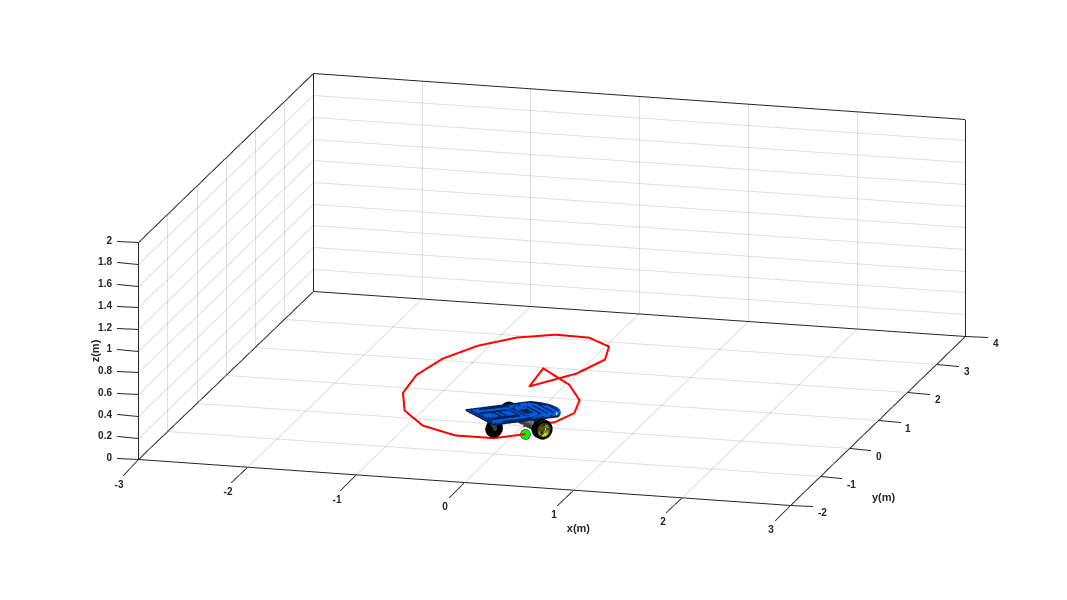

%%%%%%%%%%%%%%%%%%%%% PARÁMETROS DEL ROBOT %%%%%%%%%%%%%%%%%%%%%

r = 0.1;   % Radio de las ruedas (m)
L = 0.4;   % Distancia entre ruedas (m)
ts = 1.0;  % Tiempo por paso (s)

% Entradas de velocidades angulares por rueda (ωR y ωL)
wR = [4.582, 4.773, 5.291, 5.960, 6.490, -1.168, -1.364, 5.960, 5.291, 4.773, ...
      4.582, 4.773, 5.291, 5.960, 6.490, 6.686, 6.490, 5.960, 5.291, 4.773, 4.582];
wL = [1.701, 2.353, 3.676, 4.856, 5.618, 13.735, 13.472, 4.856, 3.676, 2.353, ...
      1.701, 2.353, 3.676, 4.856, 5.618, 5.881, 5.618, 4.856, 3.676, 2.353, 1.701];

N = length(wR);  % 21 muestras

% Inicialización de vectores de pose
x = zeros(1, N+1);      % Posición en x
y = zeros(1, N+1);      % Posición en y
theta = zeros(1, N+1);  % Orientación en radianes

% Pose inicial
x(1) = 0;
y(1) = 0;
theta(1) = 0;

%%%%%%%%%%%%%%%%%%% CÁLCULO DE VELOCIDADES Y POSE %%%%%%%%%%%%%%%%%%%

v = (r/2) * (wR + wL);        % Velocidad lineal v(k)
w = (r/L) * (wR - wL);        % Velocidad angular w(k)

for k = 1:N
    theta(k+1) = theta(k) + w(k) * ts;
    x(k+1) = x(k) + v(k) * cos(theta(k+1)) * ts;
    y(k+1) = y(k) + v(k) * sin(theta(k+1)) * ts;
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACIÓN 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
x1 = x;
y1 = y;
phi = theta;
hx = x;  
hy = y;

scene = figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen = get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([15 15]);
axis([-3 3 -2 4 0 2]);  % Ajusta según resultado

scale = 4;
MobileRobot_5;
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;
H2 = plot3(hx(1), hy(1), 0, 'r', 'lineWidth', 2);
plot3(x(end), y(end), 0, 'ko', 'MarkerFaceColor', 'g', 'MarkerSize', 10);  % punto final

step = 1;
for k = 1:step:N+1
    delete(H1);
    delete(H2);
    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'r', 'lineWidth', 2);
    pause(ts);
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TABLA %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tiempo = (0:N)';                         % Ahora de 0 a 21
theta_out = rad2deg(theta(:));          % Convertir orientación a grados
v_full = [v, NaN];                       % Añadir NaN al final
w_full = [w, NaN];
wR_full = [wR, NaN];
wL_full = [wL, NaN];

tabla = table( ...
    tiempo, v_full(:), w_full(:), wR_full(:), wL_full(:), ...
    x(:), y(:), theta_out, ...
    'VariableNames', {'t_s', 'v_m_s', 'w_rad_s', 'wR_rad_s', 'wL_rad_s', 'x_m', 'y_m', 'theta_deg'});

disp('TABLA DE POSE FINAL DESPUÉS DE CADA VELOCIDAD:')

TABLA DE POSE FINAL DESPUÉS DE CADA VELOCIDAD:


disp(tabla)

    t_s     v_m_s     w_rad_s    wR_rad_s    wL_rad_s       x_m         y_m        theta_deg 
    ___    _______    _______    ________    ________    _________    ________    ___________

     0     0.31415    0.72025      4.582       1.701             0           0              0
     1      0.3563      0.605      4.773       2.353       0.23613      0.2072         41.267
     2     0.44835    0.40375      5.291       3.676       0.32274     0.55282         75.931
     3      0.5408      0.276       5.96       4.856        0.2521     0.99557         99.064
     4      0.6054      0.218       6.49       5.618      0.024596      1.4862         114.88
     5     0.62835    -3.7257     -1.168      13.735      -0.34284   

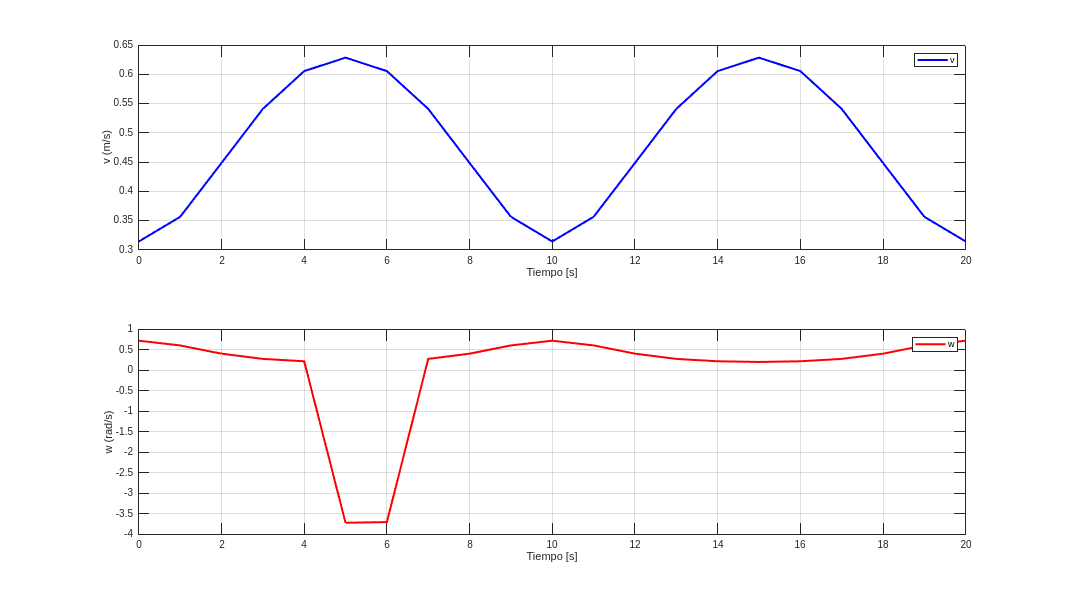

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% GRAFICAS %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

sizeScreen = get(0, 'ScreenSize');
t = tiempo;

% --------- v(t) y w(t) ---------
graph = figure;
set(graph, 'position', sizeScreen);

subplot(211)
plot(t, v_full, 'b', 'LineWidth', 2), grid on
xlabel('Tiempo [s]')
ylabel('v (m/s)')
legend('v')

subplot(212)
plot(t, w_full, 'r', 'LineWidth', 2), grid on
xlabel('Tiempo [s]')
ylabel('w (rad/s)')
legend('w')

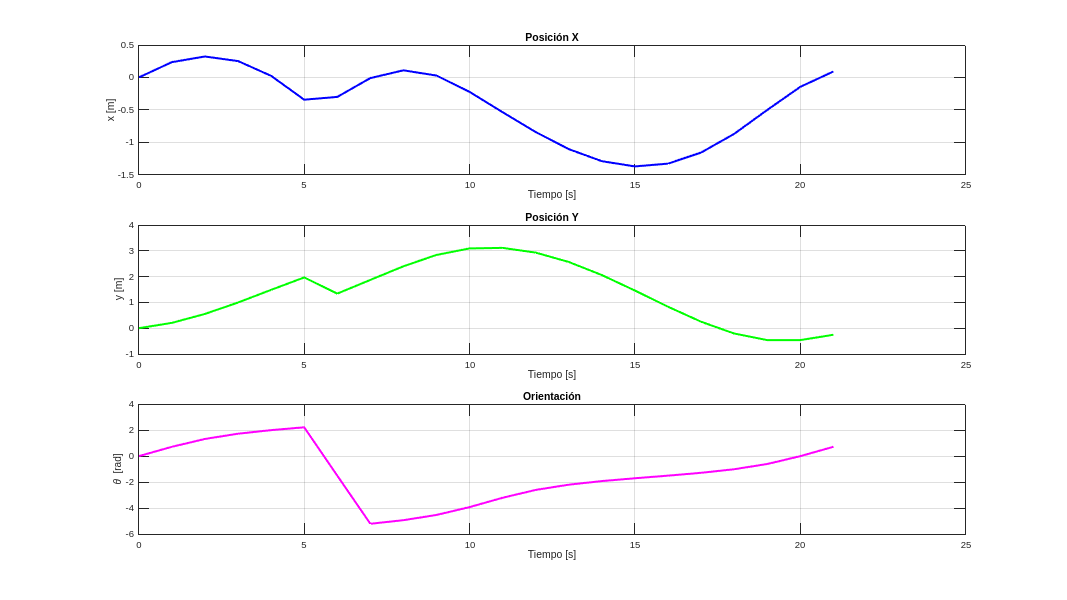


% --------- Pose del robot: x(t), y(t), theta(t) ---------
pose_graph = figure;
set(pose_graph, 'position', sizeScreen);

subplot(311)
plot(t, x, 'b', 'LineWidth', 2), grid on
xlabel('Tiempo [s]')
ylabel('x [m]')
title('Posición X')

subplot(312)
plot(t, y, 'g', 'LineWidth', 2), grid on
xlabel('Tiempo [s]')
ylabel('y [m]')
title('Posición Y')

subplot(313)
plot(t, theta, 'm', 'LineWidth', 2), grid on
xlabel('Tiempo [s]')
ylabel('\theta [rad]')
title('Orientación')

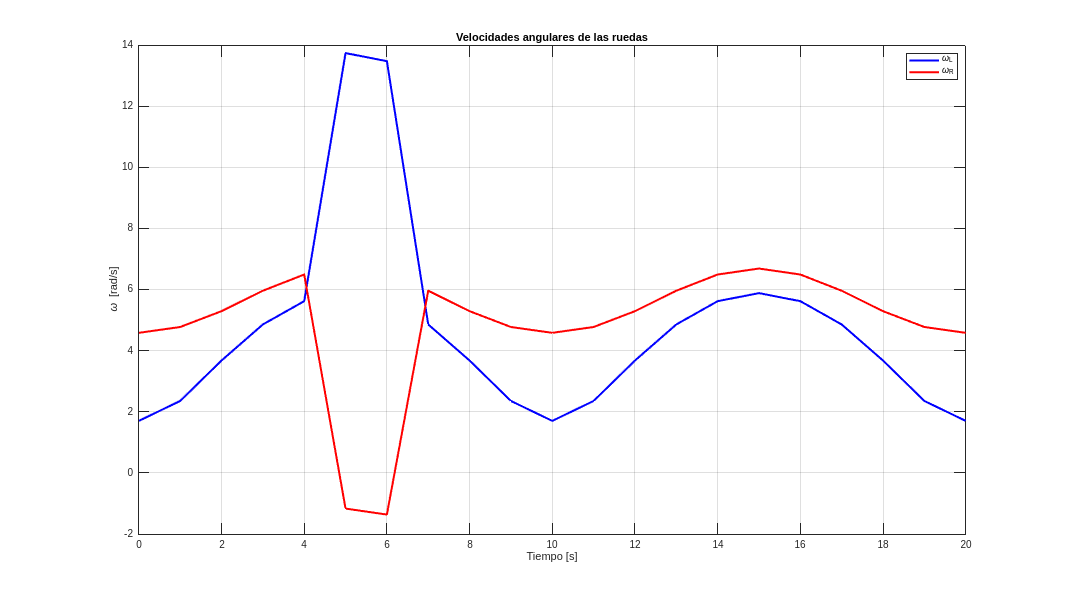


% --------- Velocidades angulares de ruedas ---------
wheel_graph = figure;
set(wheel_graph, 'position', sizeScreen);

plot(t, wL_full, 'b', 'LineWidth', 2), hold on
plot(t, wR_full, 'r', 'LineWidth', 2), grid on
xlabel('Tiempo [s]')
ylabel('\omega [rad/s]')
legend('\omega_L', '\omega_R')
title('Velocidades angulares de las ruedas')

s

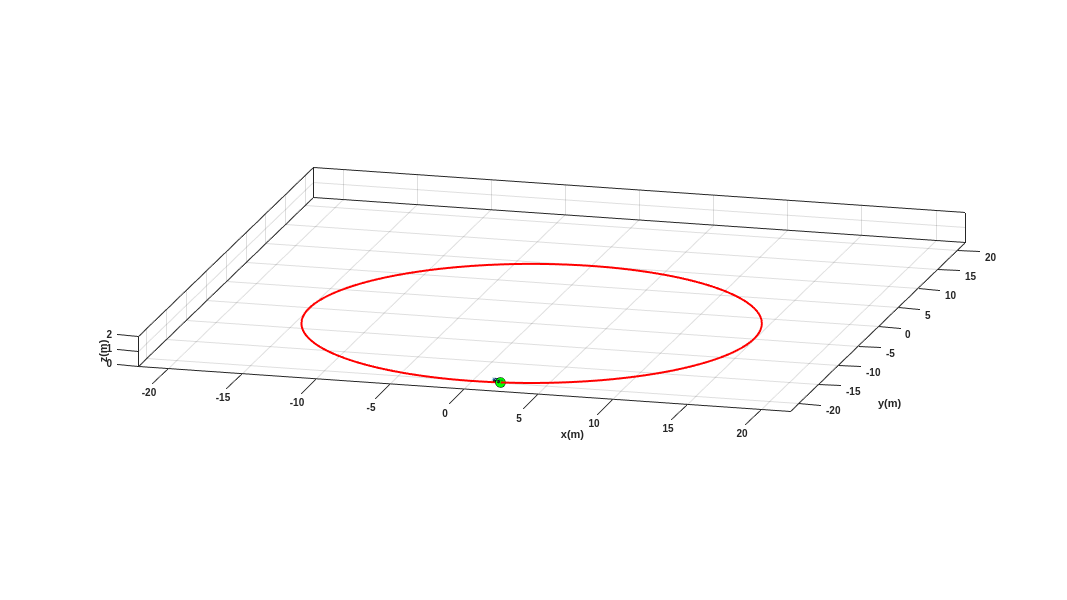

clear; clc;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tf = 96;              % Tiempo de simulación en segundos
ts = 0.1;              % Tiempo de muestreo en segundos
t = 0:ts:tf;           % Vector de tiempo
N = length(t);         % Número de muestras

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros(1, N+1);    % Posición x del robot
y1 = zeros(1, N+1);    % Posición y del robot
phi = zeros(1, N+1);   % Orientación del robot en radianes

x1(1) = 0;             % Posición inicial x
y1(1) = -20;           % Posición inicial y
phi(1) = 0;            % Orientación inicial

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1, N+1);    % Posición x del punto de control
hy = zeros(1, N+1);    % Posición y del punto de control
hx(1) = x1(1);
hy(1) = y1(1);

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

u = 1 * ones(1, N);       % Velocidad lineal de referencia
w = ones(1, N) / 15;      % Velocidad angular de referencia

%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k = 1:N
    phi(k+1) = phi(k) + w(k) * ts;  % Integración de orientación

    % Modelo cinemático diferencial
    xp1 = u(k) * cos(phi(k+1));
    yp1 = u(k) * sin(phi(k+1));

    x1(k+1) = x1(k) + xp1 * ts;
    y1(k+1) = y1(k) + yp1 * ts;

    hx(k+1) = x1(k+1);
    hy(k+1) = y1(k+1);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACIÓN 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

scene = figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen = get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([15 15]);
axis([-22 22 -22 22 0 2]); % Ajustado a la trayectoria circular

scale = 4;
MobileRobot_5;
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;
H2 = plot3(hx(1), hy(1), 0, 'r', 'lineWidth', 2);
plot3(x1(end), y1(end), 0, 'ko', 'MarkerFaceColor', 'g', 'MarkerSize', 10);  % Punto final

step = 1;
for k = 1:step:N
    delete(H1);
    delete(H2);
    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'r', 'lineWidth', 2);
    pause(ts);
end

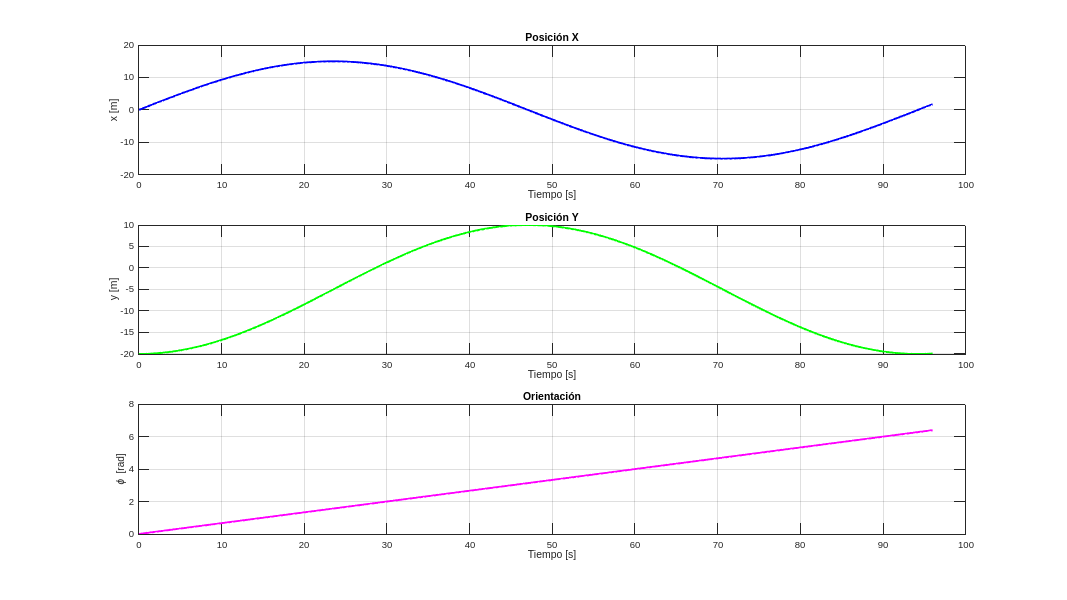


%%%%%%%%%%%%%%%%%%% CÁLCULO DE VELOCIDADES ANGULARES DE LAS RUEDAS %%%%%%%%%%%%%%%%%%%

r = 0.1; % Radio de las ruedas (m)
L = 0.4; % Distancia entre ruedas (m)

wl = zeros(1, N); % Velocidad angular de rueda izquierda
wr = zeros(1, N); % Velocidad angular de rueda derecha

for k = 1:N
    wl(k) = (2 * u(k) - w(k) * L) / (2 * r);
    wr(k) = (2 * u(k) + w(k) * L) / (2 * r);
end

%%%%%%%%%%%%%%%%%%% GRAFICAR POSE Y VELOCIDADES ANGULARES %%%%%%%%%%%%%%%%%%%

pose_graph = figure;
set(pose_graph, 'position', sizeScreen);

subplot(311)
plot(t, x1(1:N), 'b', 'LineWidth', 2), grid on
xlabel('Tiempo [s]'), ylabel('x [m]'), title('Posición X');

subplot(312)
plot(t, y1(1:N), 'g', 'LineWidth', 2), grid on
xlabel('Tiempo [s]'), ylabel('y [m]'), title('Posición Y');

subplot(313)
plot(t, phi(1:N), 'm', 'LineWidth', 2), grid on
xlabel('Tiempo [s]'), ylabel('\phi [rad]'), title('Orientación');

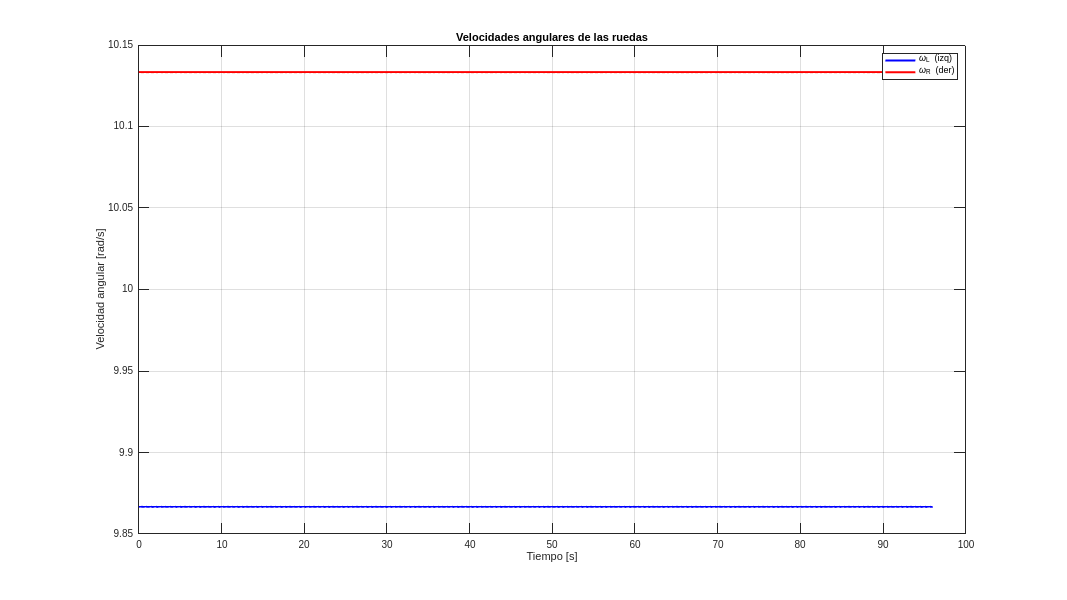


wheel_graph = figure;
set(wheel_graph, 'position', sizeScreen);
plot(t, wl, 'b', 'LineWidth', 2), hold on
plot(t, wr, 'r', 'LineWidth', 2), grid on
xlabel('Tiempo [s]')
ylabel('Velocidad angular [rad/s]')
legend('\omega_L (izq)', '\omega_R (der)')
title('Velocidades angulares de las ruedas')


%%%%%%%%%%%%%%%%%%% TABLA MUESTREADA CADA 5 SEGUNDOS %%%%%%%%%%%%%%%%%%%

muestreo_intervalo = 5;                              % Intervalo de muestreo en segundos
indices_muestreados = 1 : muestreo_intervalo/ts : N; % Cada 5 segundos
tiempos_muestreados = t(indices_muestreados)';       % Tiempo en segundos
wr_muestreados = wr(indices_muestreados)';           % ω_R muestreado
wl_muestreados = wl(indices_muestreados)';           % ω_L muestreado

tabla_muestreo = table(tiempos_muestreados, wr_muestreados, wl_muestreados, ...
    'VariableNames', {'Tiempo_s', 'omega_R_rad_s', 'omega_L_rad_s'});

disp('Tabla de velocidades angulares muestreadas cada 5 segundos:')

Tabla de velocidades angulares muestreadas cada 5 segundos:


disp(tabla_muestreo)

    Tiempo_s    omega_R_rad_s    omega_L_rad_s
    ________    _____________    _____________

        0          10.133           9.8667    
        5          10.133           9.8667    
       10          10.133           9.8667    
       15          10.133           9.8667    
       20          10.133           9.8667    
       25          10.133           9.8667    
       30          10.133           9.8667    
       35          10.133           9.8667    
       40          10.133           9.8667    
       45          10.133           9.8667    
       50          10.133           9.8667    
       55          10.133           9.8667    
       60          10.133           9.8667    
       65          10.133           9.8667    
       70          10.133           9.8667    
       75          10.133           9.8667    
       80          10.133           9.8667    
    